Check for leakages

clear
addpath(genpath(pwd));

load battledata.mat

TQ = InflowData1.DatetimeCETCESTDDMMYYYYHHmm;
Q = table2array(InflowData1(:,2:11));
TW = WeatherData1.DatetimeCETCESTDDMMYYYYHHmm;
W = table2array(WeatherData1(:,2:5));
dt = datetime(TQ, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');

plot figure

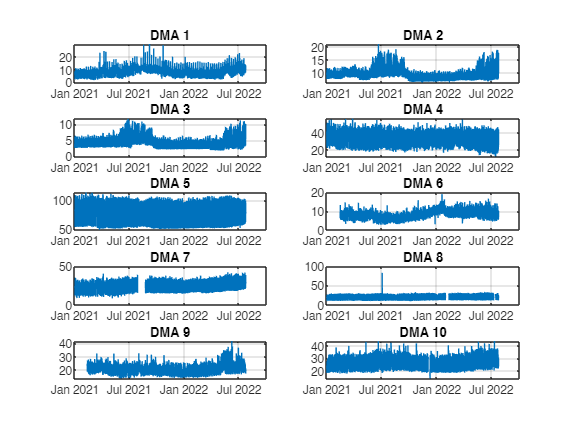

for i = 1:10
    subplot(5,2,i);
    plot(TQ,Q(:,i));  
    title(['DMA ' num2str(i)]);
    grid on
end

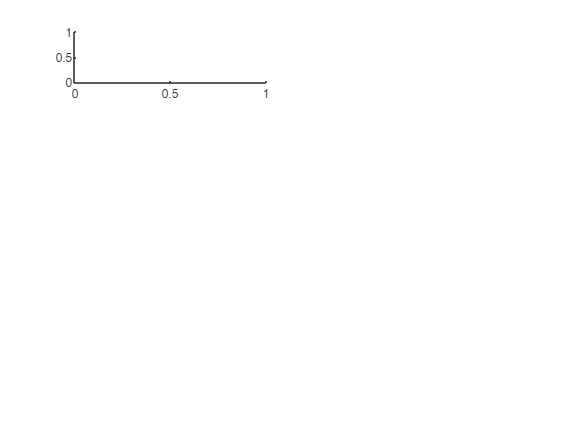

Unrecognized function or variable 'yearshift'.

% Extract the year from each datetime
years = year(dt);

% Find the unique years in your data
uniqueYears = unique(years);

% Number of unique years
numYears = length(uniqueYears);

% Create a figure for the plots
figure;

% Loop through each DMA
for i = 1:10
    subplot(5,2,i);
    hold on;  % Hold on to overlay plots
    
    % Identify data from 2021 and 2022
    indices_2021 = years == 2021;
    indices_2022 = years == 2022;
    
    % Shift 2022 data to align with 2021
    shiftedDt_2022 = dt(indices_2022) - yearshift(dt(indices_2022), -1);
    
    % Plot 2021 data
    plot(dt(indices_2021), Q(indices_2021, i), 'b');  % Blue for 2021
    
    % Plot shifted 2022 data
    plot(shiftedDt_2022, Q(indices_2022, i), 'r');  % Red for 2022
    
    % Add title, grid, and legend
    title(['DMA ' num2str(i)]);
    grid on;
    legend('2021', '2022 shifted to 2021', 'Location', 'best');
    hold off;  % Release the hold
end

% Initialize the MNF matrix to store minimum values for each DMA
MNF = zeros(numel(unique(dateshift(dt, 'start', 'day'))), 10);

% Loop through each DMA
for i = 1:10
    % Extract the time series for the current DMA
    currentQ = Q(:,i);
    
    % Find unique days
    uniqueDays = unique(dateshift(dt, 'start', 'day'));
    
    % Loop through each day
    for j = 1:length(uniqueDays)
        % Find the indices for the current day
        dayIndices = dt >= uniqueDays(j) & dt < uniqueDays(j) + days(1);
        
        % Find the minimum value for the current day and current DMA
        MNF(j,i) = nanmin(currentQ(dayIndices));
    end
end

% Plotting the results
figure;  % Ensure a new figure is created for the plots
for i = 1:10
    subplot(5,2,i);
    plot(uniqueDays, MNF(:,i));  
    title(['MNF DMA ' num2str(i)]);
    grid on
end

% Determine the number of weeks
numWeeks = ceil(days(uniqueDays(end) - uniqueDays(1))/7);

% Initialize the matrix for median MNF per week
medianMNFPerWeek = zeros(numWeeks, 10);

% Calculate median MNF per week for each DMA
for i = 1:10
    for week = 1:numWeeks
        % Define the week's range
        weekStart = uniqueDays(1) + days(7*(week-1));
        weekEnd = weekStart + days(7);
        
        % Find the indices for the current week
        weekIndices = uniqueDays >= weekStart & uniqueDays < weekEnd;
        
        % Calculate the median value for the current week and current DMA
        medianMNFPerWeek(week,i) = nanmedian(MNF(weekIndices,i));
    end
end
% Plotting the original Q values and the median weekly MNF
figure;  % Create a new figure for the plots
for i = 1:10
    subplot(5,2,i);
    
    % Plot original Q values
    plot(dt, Q(:,i));
    hold on;  % Hold on to add more to the current plot
    
    % Plot median MNF per week as horizontal lines
    for week = 1:numWeeks
        weekStart = uniqueDays(1) + days(7*(week-1));
        weekEnd = weekStart + days(7);
        line([weekStart, weekEnd], [medianMNFPerWeek(week, i), medianMNFPerWeek(week, i)], 'Color', 'r', 'LineWidth', 2);
    end
    
    % Add title and grid
    title(['DMA ' num2str(i) ' with Median Weekly MNF']);
    grid on;
    hold off;  % Release the plot
end


% Remove the errors
% Initialize the MNF matrix to store minimum values for each DMA
nonLeakageMNF = [0,0,0,0,0,0,0,0,0,0];  % Example values, one for each DMA

% Initialize the matrix for estimated leakage per hour
estimatedLeakage = zeros(size(Q));

% Calculate estimated leakage for each hour for each DMA
for i = 1:10
    % Get the weekly median MNF for the current DMA
    currentMedianMNF = interp1(1:numWeeks, medianMNFPerWeek(:,i), ceil((1:length(dt))/168), 'previous', 'extrap');
    
    % Calculate the estimated leakage for each hour
    for j = 1:length(dt)
        if Q(j,i) - nonLeakageMNF(i) > 0  % Only calculate if actual MNF is greater than non-leakage MNF
            estimatedLeakage(j,i) = currentMedianMNF(ceil(j/168)) - nonLeakageMNF(i);
        else
            estimatedLeakage(j,i) = 0;  % No leakage if actual MNF is less than or equal to non-leakage MNF
        end
    end
end
% Plotting the estimated leakage
figure;  % Create a new figure for the plots
for i = 1:10
    subplot(5,2,i);
    plot(dt, estimatedLeakage(:,i), 'b');
    title(['Estimated Leakage for DMA ' num2str(i)]);
    xlabel('Time');
    ylabel('Leakage (L/s)');
    grid on;
end

Remove low frequency trend

TotalQ = sum(Q'); % do not consider days with NAN
nonnan = ~isnan(TotalQ)

FourierTerms = 1;
w = 2 * pi/(365*24);
KDW = K(nonnan);
FDW = TotalQ(nonnan)';

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

A0 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))'];
f4 = A0*rcoef;

figure
plot(T,TotalQ)
hold on
plot(T,f4)
grid on

figure
plot(T,TotalQ./f4)
MeanValue = nanmean(TotalQ./f4)
grid on

Compute MNF

nightStart = 0; % 00:00 in 24-hour format
nightEnd = 6; % 04:00 in 24-hour format
nightIndices = (T.Hour >= 0) & (T.Hour <= 6);

maxDate = max(T);
minDate = min(T);
% Calculate the difference in days
dateDifference = maxDate - minDate;
% Convert the duration to a scalar number of days
totalDays = floor(days(dateDifference))

for i=1:10
    DQ = reshape(Q((1:24*totalDays),i), 24, totalDays);
    mnf(i,:) = nanmin(DQ(1:6,:))
end

